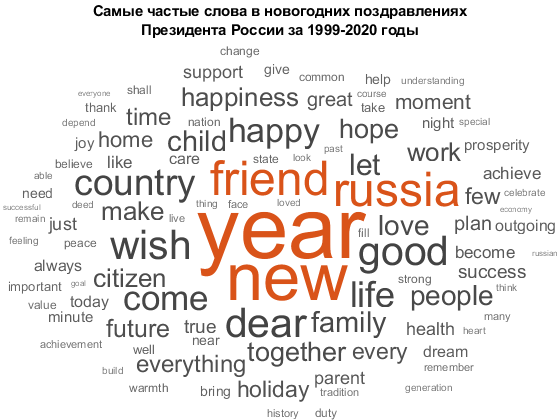

%doc_struct.ruen.preproc_text = strings(size(doc_struct.ruen.transcript));

doc_struct.ruen.preproc_text = preprocessText(doc_struct.ruen.transcript);

remove_word_arr = [
    "the" "say" "second" "own"
];

doc_struct.ruen.preproc_text = removeWords(doc_struct.ruen.preproc_text, remove_word_arr);

doc_struct.ruen.tokenized = tokenizedDocument(doc_struct.ruen.preproc_text);

doc_struct.ruen.bag = bagOfWords(doc_struct.ruen.preproc_text);

wordcloud(doc_struct.ruen.bag);

title({'Самые частые слова в новогодних поздравлениях', ...
    'Президента России за 1999-2020 годы'})

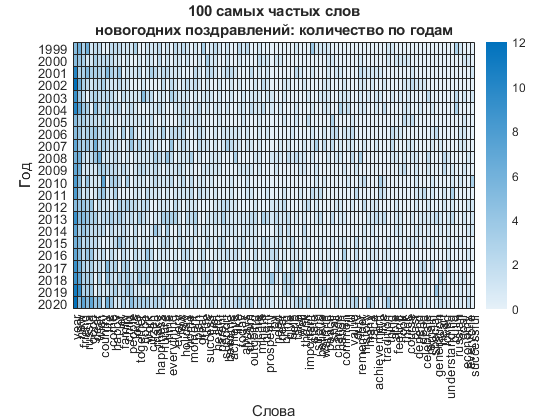

% top 100 words data by years for heat map 
top100 = topkwords(doc_struct.ruen.bag, 100);

doc_struct.ruen.top100 = top100;

top100_vocab_idx = zeros(100, 1);

for i = 1:100
    top100_vocab_idx(i, 1) = find(doc_struct.ruen.bag.Vocabulary == top100.Word(i));
end

heatmap(doc_struct.ruen.bag.Counts(:, top100_vocab_idx));
ax=gca;
ax.XData = doc_struct.ruen.bag.Vocabulary(top100_vocab_idx);
ax.YData = 1999:2020;

title({'100 самых частых слов', ...
    'новогодних поздравлений: количество по годам'});

xlabel('Слова');
ylabel('Год');

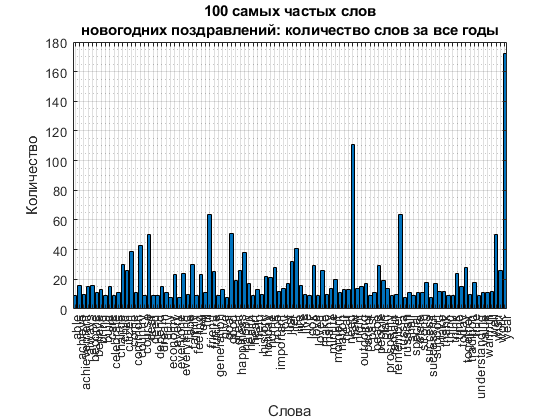


% top 100 words overall
bar(categorical(top100.Word), top100.Count)

grid on;
grid minor;

title({'100 самых частых слов', ...
    'новогодних поздравлений: количество слов за все годы'});

xlabel('Слова');
ylabel('Количество');

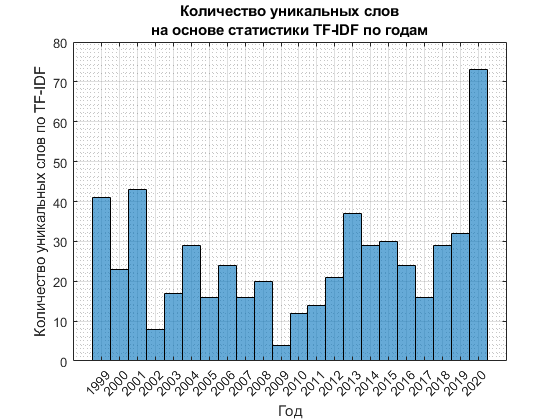

% tf-idf features
tf_idf = tfidf(doc_struct.ruen.bag,'TFWeight','binary');

% find elements with max TF-IDF score
[row, col, val] = find(2.5 < tf_idf);

histogram(row, 'BinMethod', 'integers');
xticks(1:22);
xticklabels(1999:2020);

grid on;
grid minor;

xlabel('Год');
ylabel('Количество уникальных слов по TF-IDF');
title({'Количество уникальных слов', ...
    'на основе статистики TF-IDF по годам'})

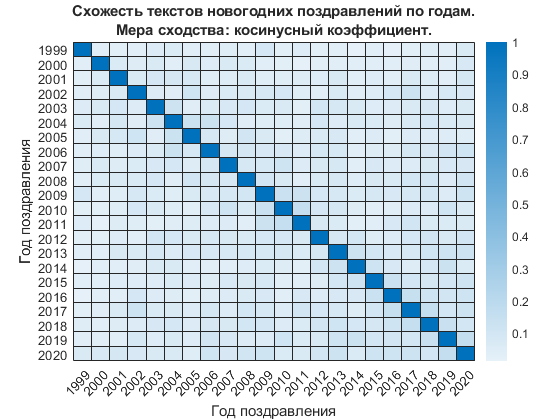

% cosine similarity
cos_sim = cosineSimilarity(doc_struct.ruen.bag);

heatmap(cos_sim);
xlabel('Год поздравления');

ylabel('Год поздравления');

ax=gca;
ax.XData = doc_struct.ruen.year;
ax.YData = doc_struct.ruen.year;

title({'Схожесть текстов новогодних поздравлений по годам.', ...
    'Мера сходства: косинусный коэффициент.'});

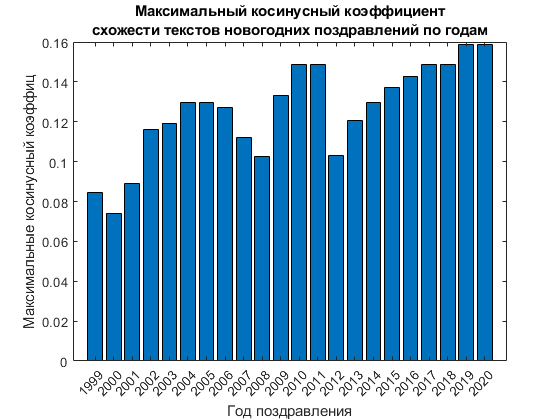


% Периодичность по президентским срокам с максимумом в середине срока
bar(max(cos_sim+diag(repelem(-1,22))))

xticks(1:1:22);
xticklabels(doc_struct.ruen.year);

xlabel('Год поздравления');
ylabel('Максимальные косинусный коэффиц');

title({'Максимальный косинусный коэффициент', ...
    'схожести текстов новогодних поздравлений по годам'});

% Будет ли тот же результат в BM25 и других метриках?

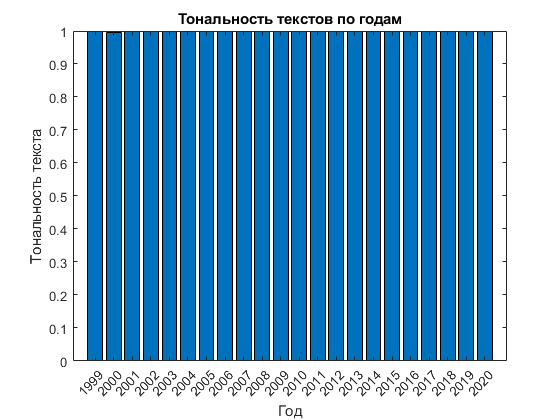

% sentiment analysis
% extremely positive!
sentiment_vader = vaderSentimentScores(doc_struct.ruen.tokenized);

% not needed: almost all are equal to 1
%sentiment_ratio = ratioSentimentScores(doc_struct.ruen.tokenized);

bar(sentiment_vader);

title('Тональность текстов по годам');

xticks(1:22);
xticklabels(doc_struct.ruen.year);

xlabel('Год');
ylabel('Тональность текста');

% summary
%[summary, scores] = extractSummary(doc_struct.ruen.tokenized);
%bar(scores);
%join(joinWords(summary)); % ???

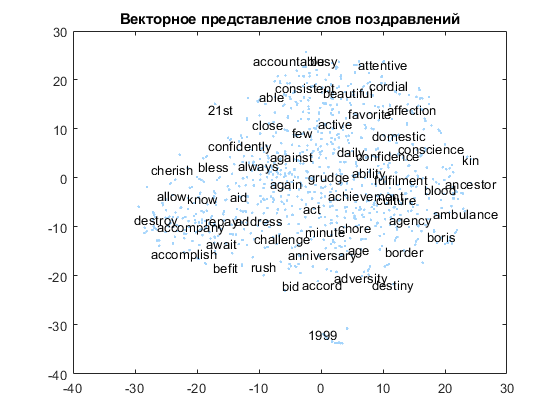

% word embedding with scatter plot
emb = fastTextWordEmbedding;

% missing words in embedding vacabulary
vocab_diff = setdiff(doc_struct.ruen.bag.Vocabulary, emb.Vocabulary);

greeting_emb_vocab = setdiff(doc_struct.ruen.bag.Vocabulary, vocab_diff);

V = word2vec(emb, greeting_emb_vocab);

XY = tsne(V);

textscatter(XY, greeting_emb_vocab);
title("Векторное представление слов поздравлений");

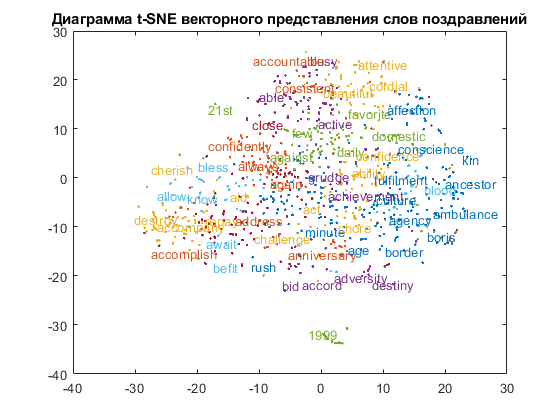

% how to choose k?
% https://medium.com/analytics-vidhya/how-to-determine-the-optimal-k-for-k-means-708505d204eb
cidx = kmeans(V, 25, 'dist','sqeuclidean');

textscatter(XY,greeting_emb_vocab,'ColorData',categorical(cidx));
title("Диаграмма t-SNE векторного представления слов поздравлений");

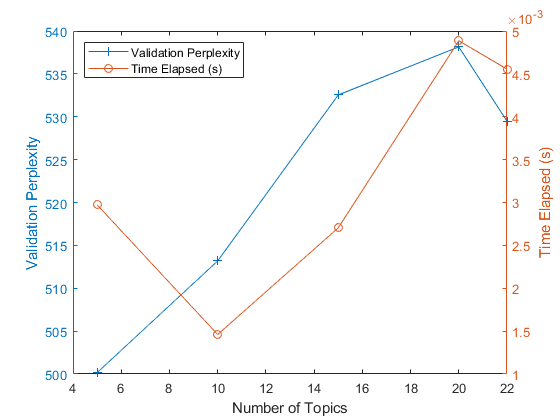

% https://www.mathworks.com/help/textanalytics/ug/choose-number-of-topics-for-LDA-model.html
% number of topics for LDA model

numDocuments = numel(doc_struct.ruen.tokenized);
cvp = cvpartition(numDocuments,'HoldOut',0.1);
documentsTrain = doc_struct.ruen.tokenized(cvp.training);
documentsValidation = doc_struct.ruen.tokenized(cvp.test);

bag = bagOfWords(documentsTrain);
bag = removeInfrequentWords(bag,2);
bag = removeEmptyDocuments(bag);

numTopicsRange = [5:5:20 22];

validationPerplexity = zeros(size(numTopicsRange));
timeElapsed = zeros(size(numTopicsRange));

for i = 1:numel(numTopicsRange)
    numTopics = numTopicsRange(i);
    
    mdl = fitlda(doc_struct.ruen.bag,numTopics, ...
        'Solver','savb', ...
        'Verbose',0);
    
    [~,validationPerplexity(i)] = logp(mdl,documentsValidation);
    timeElapsed(i) = mdl.FitInfo.History.TimeSinceStart(end);
end

figure
yyaxis left
plot(numTopicsRange,validationPerplexity,'+-')
ylabel("Validation Perplexity")

yyaxis right
plot(numTopicsRange,timeElapsed,'o-')
ylabel("Time Elapsed (s)")

legend(["Validation Perplexity" "Time Elapsed (s)"],'Location','northwest')
xlabel("Number of Topics")


% from graph: 20 topics

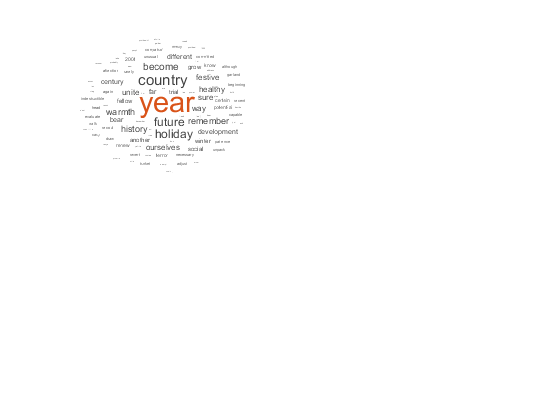

% https://www.mathworks.com/help/textanalytics/ug/analyze-text-data-using-topic-models.html
% fit LDA model

numTopics = 20;
mdl = fitlda(doc_struct.ruen.bag, numTopics, 'Verbose', 0);

figure;
for topicIdx = 1:4
    subplot(2,2,topicIdx)
    wordcloud(mdl,topicIdx);
    title("Topic " + topicIdx)
end

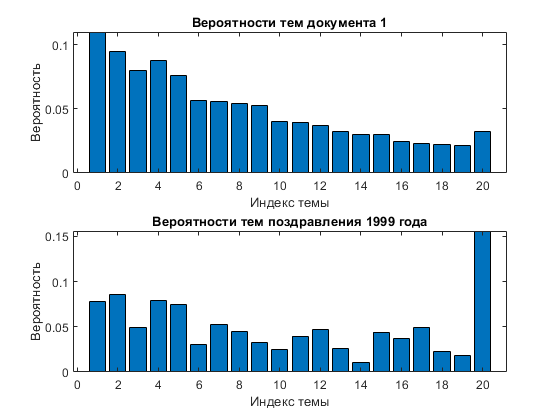

new_document_1 = tokenizedDocument(lower("Yeltsin is the first president of Russia."));
topic_mixture_1 = transform(mdl,new_document_1);

% check topic with 1999 year text
new_document_1_check = doc_struct.ruen.tokenized(1);
topic_mixture_1_check = transform(mdl,new_document_1_check);

figure
subplot(2, 1, 1)
bar(topic_mixture_1)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем документа 1")

subplot(2, 1, 2)
bar(topic_mixture_1_check)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем поздравления 1999 года")

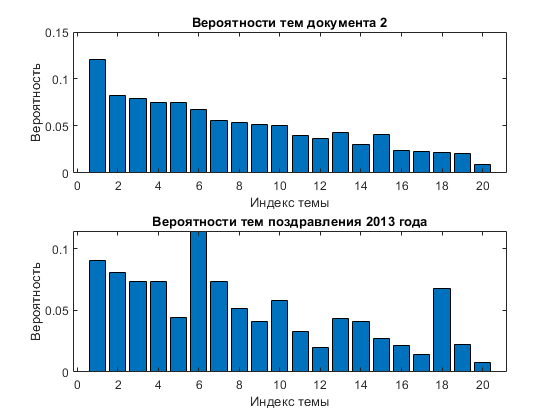


new_document_2 = tokenizedDocument(lower("Natural calamity, flood, Far East."));
topic_mixture_2 = transform(mdl,new_document_2);

% check topic with 2013 year text
new_document_2_check = doc_struct.ruen.tokenized(15);
topic_mixture_2_check = transform(mdl,new_document_2_check);

figure
subplot(2, 1, 1)
bar(topic_mixture_2)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем документа 2")

subplot(2, 1, 2)
bar(topic_mixture_2_check)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем поздравления 2013 года")

% % https://www.mathworks.com/help/textanalytics/ug/generate-text-using-character-embeddings.html
% % generate text using word embedding
% 
% % combined text of all greetings
% greet_text = join(doc_struct.ruen.transcript);
% 
% newlineCharacter = compose("\x00B6");
% whitespaceCharacter = compose("\x00B7");
% greet_text = replace(greet_text, [newline " "], [newlineCharacter whitespaceCharacter]);
% 
% endOfTextCharacter = compose("\x2403");
% numDocuments = numel(greet_text);
% for i = 1:numDocuments
%     characters = greet_text{i};
%     X = double(characters);
%     
%     % Create vector of categorical responses with end of text character.
%     charactersShifted = [cellstr(characters(2:end)')' endOfTextCharacter];
%     Y = categorical(charactersShifted);
%     
%     XTrain{i} = X;
%     YTrain{i} = Y;
% end
% 
% numObservations = numel(XTrain);
% for i=1:numObservations
%     sequence = XTrain{i};
%     sequenceLengths(i) = size(sequence,2);
% end
% 
% [~,idx] = sort(sequenceLengths);
% XTrain = XTrain(idx);
% YTrain = YTrain(idx);
% 
% inputSize = size(XTrain{1},1);
% numClasses = numel(categories([YTrain{:}]));
% numCharacters = max([greet_text{:}]);
% 
% layers = [
%     sequenceInputLayer(inputSize)
%     wordEmbeddingLayer(200,numCharacters)
%     lstmLayer(400,'OutputMode','sequence')
%     dropoutLayer(0.2);
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer];
% 
% options = trainingOptions('adam', ...
%     'MiniBatchSize',32,...
%     'InitialLearnRate',0.01, ...
%     'GradientThreshold',1, ...
%     'Shuffle','never', ...
%     'Plots','training-progress', ...
%     'Verbose',false);
% 
% net = trainNetwork(XTrain,YTrain,layers,options);
% 
% initialCharacters = extractBefore(greet_text,2);
% firstCharacter = datasample(initialCharacters,1);
% generatedText = firstCharacter;
% 
% X = double(char(firstCharacter));
% 
% vocabulary = string(net.Layers(end).ClassNames);
% 
% maxLength = 500;
% while strlength(generatedText) < maxLength
%     % Predict the next character scores.
%     [net,characterScores] = predictAndUpdateState(net,X,'ExecutionEnvironment','cpu');
%     
%     % Sample the next character.
%     newCharacter = datasample(vocabulary,1,'Weights',characterScores);
%     
%     % Stop predicting at the end of text.
%     if newCharacter == endOfTextCharacter
%         break
%     end
%     
%     % Add the character to the generated text.
%     generatedText = generatedText + newCharacter;
%     
%     % Get the numeric index of the character.
%     X = double(char(newCharacter));
% end
% 
% generatedText = replace(generatedText,[newlineCharacter whitespaceCharacter],[newline " "])
% 
% % net = resetState(net);

% textrank keywords
doc_struct.ruen.textrank = textrankKeywords(doc_struct.ruen.tokenized, 'MaxNumKeywords', 2);

if 1 < size(doc_struct.ruen.textrank.Keyword, 2)
    doc_struct.ruen.textrank.Keyword = strip(join(doc_struct.ruen.textrank.Keyword));
end

doc_struct.ruen.textrank.Keyword

ans = 44×1 string array
    "health happy new year happy new"
    "president russia new year"
    "new year new"
    "friend good health peace"
    "happy new year dear friend happy"
    "good result previous year"
    "year new year"
    "threshold third year third"
    "new year"
    "year good"
    "new year dear friend"
    "russian nation new"
    "dear citizen russia dear friend"
    "important plan economy social"
    "dear citizen russia dear friend few"
    "family holiday new year"
    "citizen russia dear friend"
    "year year russia"
    "wish wish happiness happy new year"
    "moment wish loved dear"
    "family country new year"
    "russia friends tonight few unique"
    "happy new year"
    "new year holiday"
    "wish happy new year"
    "new year country"
    "important hope new year"
    "effort work achievement trust support"
    "new year night time"
    "friend new year"


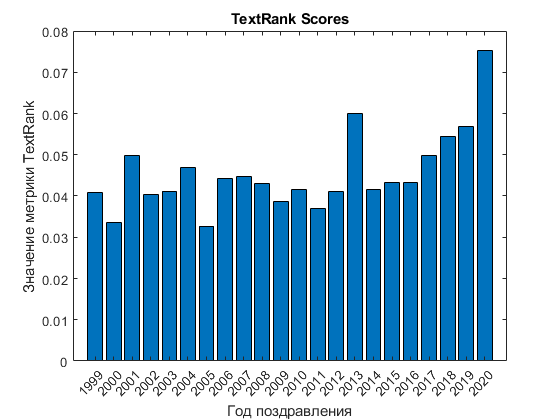


writetable(doc_struct.ruen.textrank, 'ruen.textrank.xls')

% TextRank Scores
doc_struct.ruen.textrank_scores = textrankScores(doc_struct.ruen.bag);

figure;
bar(doc_struct.ruen.textrank_scores);

xticks(1:22);
xticklabels(doc_struct.ruen.year);
xlabel("Год поздравления");
ylabel("Значение метрики TextRank");
title("TextRank Scores");


% rakerank keywords
doc_struct.ruen.rakerank = rakeKeywords(doc_struct.ruen.tokenized, 'MaxNumKeywords', 2);

if 1 < size(doc_struct.ruen.rakerank.Keyword, 2)
    doc_struct.ruen.rakerank.Keyword = strip(join(doc_struct.ruen.rakerank.Keyword));
end

doc_struct.ruen.rakerank.Keyword

ans = 22×1 string array
    "dear friend new year eve family plan gather round just probably listen address president boris yeltsin thing take different turn december 1999 russia first president decide resign ask address russian people today power head state turn today presidential election hold three month assure vacuum power minute promise attempt act contrary russian law constitution cut short state stand firm protect freedom speech freedom conscience freedom mass medium ownership right fundamental element civilise society armed force federal frontier service lawenforcement agency work usual regime state continue uphold safety every russian citizen make decision stand down president act full compliance constitution able true importance boris yeltsin russia time pass clear already thanks president russia opt democracy reform move goal become strong independent state wish health happiness boris yeltsin first president russia new year always cherished kind love holiday russia holiday d